%% Robot and Map Setup with Padding
L = 0.331;          % Distance between wheels [m]
resolucion = 6;     % Cells per meter

% Apply 1-cell padding to TOP and LEFT
sm4b_padded = [zeros(1, 52); sm4b];       % Add 1 row to TOP
sm4b_padded = [zeros(53, 1), sm4b_padded]; % Add 1 column to LEFT
sm4b_fixed = sm4b_padded(1:52, 1:52);     % Trim back to 52x52

% Create maps
map = binaryOccupancyMap(52/resolucion, 52/resolucion, resolucion);
setOccupancy(map, [0 0], sm4b_fixed, 'grid');
inflatedMap = copy(map);
inflate(inflatedMap, 0.5 * L);

%% PRM Parameter Sweep Configuration
start = [0.6, 0];   % Start position [m]
goal = [8, 0];      % Goal position [m]

% Parameter ranges and results table setup (same as before)
node_range = 100:50:300;
conn_dist_range = 1.5:0.5:4.5;
results = table();
iteration = 1;

for num_nodes = node_range
    for conn_dist = conn_dist_range
        tic;
        prm = mobileRobotPRM(inflatedMap, num_nodes);
        prm.ConnectionDistance = conn_dist;

        max_retries = 3;
        retry_count = 0;
        path = [];
        path_length = NaN; % <- Initialize path_length
        status = "Unknown"; % <- Initialize status
        
        while retry_count < max_retries
            try
                path = findpath(prm, start, goal);
                break;
            catch
                retry_count = retry_count + 1;
                if retry_count == max_retries
                    status = "MaxRetriesExceeded";
                end
            end
        end

        if ~isempty(path)
            path_length = sum(sqrt(sum(diff(path).^2, 2)));
            status = "Success";
        elseif status == "Unknown"
            status = "NoPathFound";
        end

        elapsed_time = toc;
        results(iteration,:) = table(...
            num_nodes, conn_dist, path_length, status, elapsed_time, ...
            'VariableNames', {'Nodes', 'ConnDist', 'PathLength', 'Status', 'Time'});
        iteration = iteration + 1;
    end
end


%% Display Results and Visualize
[~, best_idx] = min(results.PathLength);
best_nodes = results.Nodes(best_idx);
best_dist = results.ConnDist(best_idx);

% Create best PRM
best_prm = mobileRobotPRM(inflatedMap, best_nodes);
best_prm.ConnectionDistance = best_dist;
path = findpath(best_prm, start, goal);

%% Display Formatted Results Table
disp(' ');

disp('=== PRM Optimization Results ===');

=== PRM Optimization Results ===


disp(results);

    Nodes    ConnDist    PathLength       Status          Time  
    _____    ________    __________    _____________    ________

     100       1.5            NaN      "NoPathFound"     0.51233
     100         2            NaN      "NoPathFound"     0.11162
     100       2.5         24.061      "Success"         0.14812
     100         3            NaN      "NoPathFound"     0.14682
     100       3.5         23.018      "Success"         0.16829
     100         4         17.401      "Success"        0.064639
     100       4.5         14.349      "Success"         0.07967
     150       1.5            NaN      "NoPathFound"    0.041283
     150         2         15.036      "Success"        0.080225
     150       2.5           14.9      "Success"        0.097983
     150         3            NaN      "NoPathFou


% Find best solution
valid_results = results(results.Status == "Success",:);
[~, best_idx] = min(valid_results.PathLength);
best_nodes = valid_results.Nodes(best_idx);
best_dist = valid_results.ConnDist(best_idx);

fprintf('\nBest Solution:\nNodes=%d, ConnDist=%.1fm, PathLength=%.2fm\n', ...
       best_nodes, best_dist, valid_results.PathLength(best_idx));


Best Solution:
Nodes=300, ConnDist=2.0m, PathLength=11.73m


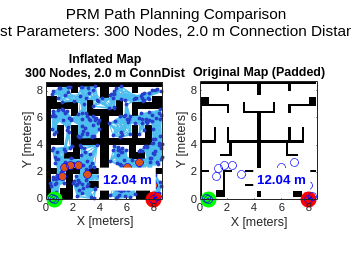

%% Side-by-Side Visualization
figure;

% Inflated Map (left subplot)
subplot(1,2,1);
show(inflatedMap);
hold on;
show(best_prm); % Show PRM roadmap
plot(start(1), start(2), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'g');
plot(goal(1), goal(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'r');
if ~isempty(path)
    plot(path(:,1), path(:,2), 'b-', 'LineWidth', 3);
    plot(path(:,1), path(:,2), 'bo', 'MarkerSize', 6);
    path_length = sum(sqrt(sum(diff(path).^2, 2)));
    text(mean(path(:,1)), mean(path(:,2)), sprintf('%.2f m', path_length), ...
         'Color', 'blue', 'FontWeight', 'bold', 'BackgroundColor', 'white');
end
title(sprintf('Inflated Map\n%d Nodes, %.1f m ConnDist', best_nodes, best_dist));

% Original Map (right subplot)
subplot(1,2,2);
show(map);
hold on;
plot(start(1), start(2), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'g');
plot(goal(1), goal(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'r');
if ~isempty(path)
    plot(path(:,1), path(:,2), 'b-', 'LineWidth', 3);
    plot(path(:,1), path(:,2), 'bo', 'MarkerSize', 6);
    text(mean(path(:,1)), mean(path(:,2)), sprintf('%.2f m', path_length), ...
         'Color', 'blue', 'FontWeight', 'bold', 'BackgroundColor', 'white');
end
title('Original Map (Padded)');

% Add main title
sgtitle(sprintf('PRM Path Planning Comparison\nBest Parameters: %d Nodes, %.1f m Connection Distance', ...
       best_nodes, best_dist));

% Define state space
stateSpace = stateSpaceSE2;
stateSpace.StateBounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];

% Validity checker
validator = validatorOccupancyMap(stateSpace);
validator.Map = inflatedMap;
validator.ValidationDistance = 0.05;

% Parameter sweep
maxIterationsRange = 300:200:900;
maxConnectionDistanceRange = 0.5:0.5:2.5;

results = table();
iteration = 1;

for maxIterations = maxIterationsRange
    for maxConnDist = maxConnectionDistanceRange
        tic;
        
        planner = plannerRRT(stateSpace, validator);
        planner.MaxIterations = maxIterations;
        planner.MaxConnectionDistance = maxConnDist;

        path = [];
        status = "Unknown";
        path_length = NaN;

        try
            [pthObj, solnInfo] = plan(planner, [start 0], [goal 0]);
            if ~isempty(pthObj.States)
                path = pthObj.States;
                path_length = sum(sqrt(sum(diff(path(:,1:2)).^2, 2)));
                status = "Success";
            else
                status = "NoPathFound";
            end
        catch
            status = "Error";
        end

        elapsed_time = toc;
        results(iteration,:) = table(...
            maxIterations, maxConnDist, path_length, status, elapsed_time, ...
            'VariableNames', {'MaxIterations', 'ConnDist', 'PathLength', 'Status', 'Time'});
        iteration = iteration + 1;
    end
end

%% Display Results and Visualization
valid_results = results(results.Status == "Success",:);
[~, best_idx] = min(valid_results.PathLength);
best_iter = valid_results.MaxIterations(best_idx);
best_conn = valid_results.ConnDist(best_idx);

fprintf('\n=== Best RRT Configuration ===\n');


=== Best RRT Configuration ===


fprintf('MaxIterations=%d, ConnDist=%.2f m, PathLength=%.2f m\n', ...
    best_iter, best_conn, valid_results.PathLength(best_idx));

MaxIterations=900, ConnDist=1.00 m, PathLength=12.78 m


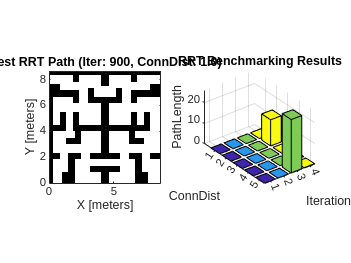


% Re-plan with best parameters
planner = plannerRRT(stateSpace, validator);
planner.MaxIterations = best_iter;
planner.MaxConnectionDistance = best_conn;
[pBest, ~] = plan(planner, [start 0], [goal 0]);

%% Plot Results
figure;
subplot(1,2,1);
show(inflatedMap);
hold on;
if ~isempty(pBest.States)
    plot(pBest.States(:,1), pBest.States(:,2), 'b-', 'LineWidth', 2);
    plot(start(1), start(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
    plot(goal(1), goal(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
end
title(sprintf('Best RRT Path (Iter: %d, ConnDist: %.1f)', best_iter, best_conn));

subplot(1,2,2);
bar3(reshape(results.PathLength, length(maxConnectionDistanceRange), []));
xlabel('Iteration');
ylabel('ConnDist');
zlabel('PathLength');
title('RRT Benchmarking Results');

if clientID > -1
    disp('Connected to CoppeliaSim');

    for i = 1:size(path, 1)
        x = path(i, 1);
        y = path(i, 2);
        z = 0.05; % fixed height for 2D nav

        % Send position as a signal or set target
        % Option 1: send as string signal (e.g., CSV string)
        signal = sprintf('%.3f,%.3f,%.3f', x, y, z);
        vrep.simxSetStringSignal(clientID, 'waypoint_signal', signal, vrep.simx_opmode_oneshot);

        % Add small pause or wait for ack in real app
        pause(0.1);
    end

    vrep.simxFinish(clientID);
else
    error('Failed to connect to CoppeliaSim');
end

Unrecognized function or variable 'clientID'.


vrep.delete(); % Clean up